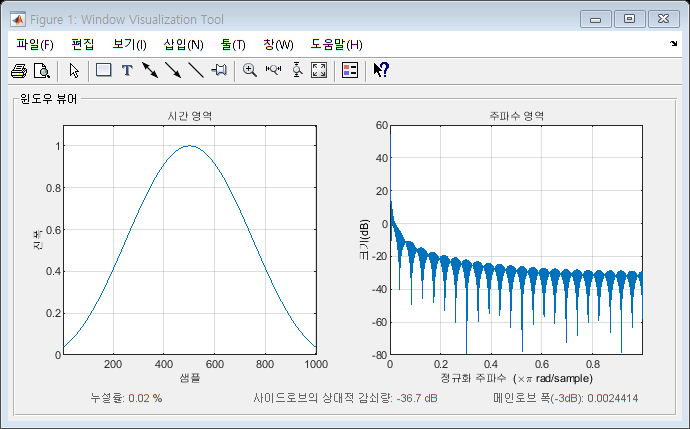

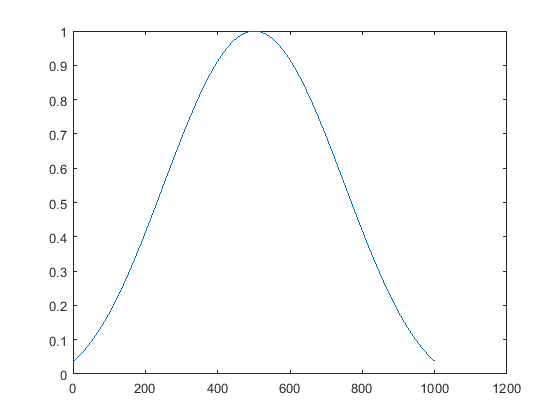

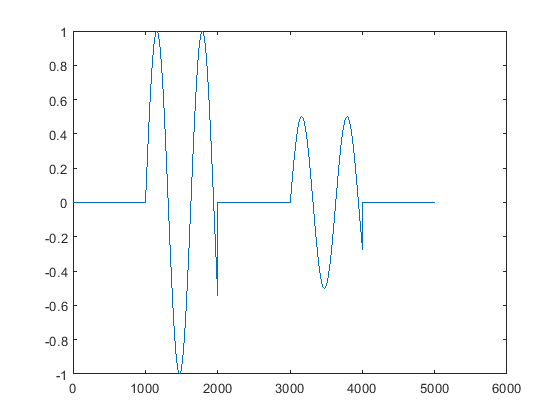

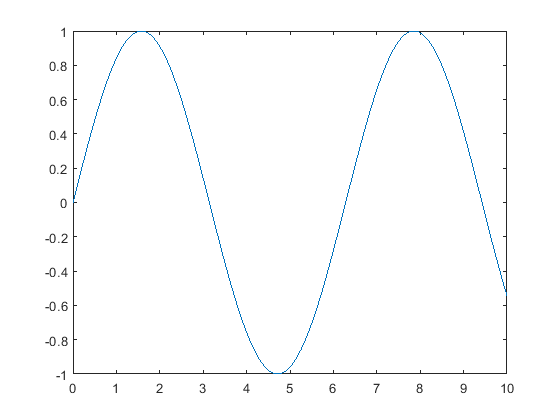

dt = 0.01;
t = 0 : dt : 10;
N = length(t);
gain1 = 1;
gain2 = 1;
startf1 = 1;
startf2 = 1;
time1 = 1;
time2 = 1;
changef1 = 2;
changef2 = 2;
number = 0;
noiseSD = 1;

% chirp signal
y1 = gain1 * chirp(t, startf1, time1, changef1); 
y2 = gain2 * chirp(t, startf2, time2, changef2);

r1 = [ zeros(1,N), y1, zeros(1,N) ];
r2 = [ zeros(1,N+50), y2, zeros(1,N-50) ];
            
r = (r1 + r2) + randn(1,length(r1 + r2))*number*noiseSD;    

% correlation
    ct1 = length(r)-N;
        for a = 0:ct1
            c(a+1) = r(a+1:a+N)*y1';
        end
                